lon = Lon.Value;
lat = Lat.Value;
height = GPS_Altitude.Value;
distance = LapDist.Value;
distance(1) = 0;
apex = [];

speed = Speed.Value;
latG = LatAccel.Value;

start = 1;
finish = length(lon);

z1 = utmzone(lat(1),lon(1));

%% Convert Data to UTM
[ellipsoid,estr] = utmgeoid(z1);
utmstruct = defaultm('utm');
utmstruct.zone = z1;
utmstruct.geoid = ellipsoid;
utmstruct = defaultm(utmstruct);

[x,y] = mfwdtran(utmstruct,lat,lon);
            
%% Normalize Data to Zero (minimum of x and y)
% Normalize x, y and z coordinates
x_norm = x-min(x);
y_norm = y-min(y);
heigth_norm = height-min(height);

%plot(x_norm, y_norm)

distance_lap = distance(start:finish)-min(distance(start:finish));
distance_lap(end)

ans = 4.5292e+03

## Corner Radius calculation

latG = smooth(latG, 3, "moving");

for i = 1:length(lat)
    R2(i) = speed(i)^2/latG(i)/9.81;
    Ri(i) = 1/R2(i);
end

min(abs(R2))

ans = 14.0751

max(R2)

ans = 5.2706e+05

max(latG)

ans = 2.3702

min(latG)

ans = -2.5191


latG(1201)

ans = 2.0257

speed(1201)

ans = 40.6507

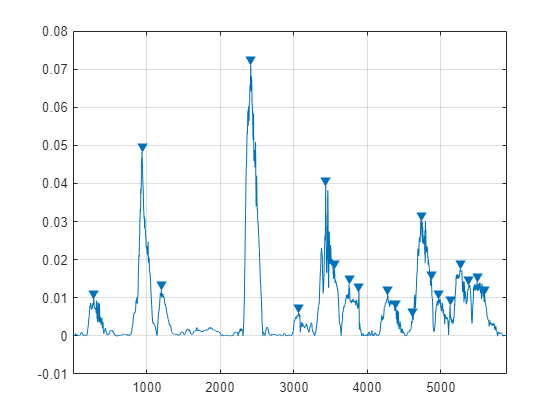


minPeakHeight = 0.00009; % Start 0.001
MinPeakDistance = 50; % Start 200
MinPeakProminence = 0.001;

minPeakHeight = 0.005; % 0.001
MinPeakDistance = 100; % 200
MinPeakProminence = 0.0005; % 0.001

findpeaks(abs(Ri),'MinPeakDistance',MinPeakDistance,'MinPeakHeight',minPeakHeight,'MinPeakProminence',MinPeakProminence)

[~, apexes] = findpeaks(abs(Ri),'MinPeakDistance',MinPeakDistance,'MinPeakHeight',minPeakHeight,'MinPeakProminence',MinPeakProminence)

apexes =          283         940        1201        2415        3071        3433        3550        3751        3885        4277        4385        4615        4731        4866        4973        5123        5265        5378        5490        5591


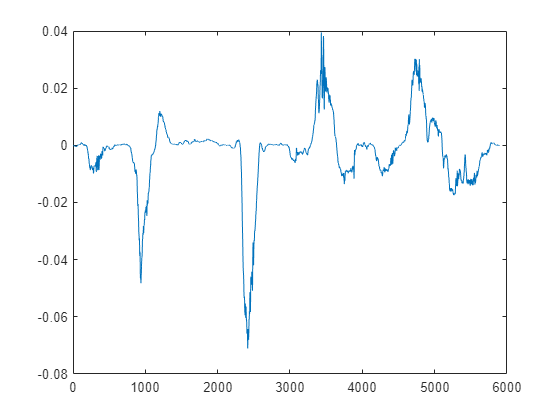

plot(Ri)

## Save Track

R2 = smooth(R2, 3, "moving");
%R_smooth = R2.*direction';  % Adding the direction of the corner (+/-)
R_smooth = R2;  % Adding the direction of the corner (+/-)

%plot(1./R2)

% Save track file
TrackData = [x_norm', y_norm', heigth_norm', distance_lap', R_smooth];


%ApexIndexes = Apexes(abs(TrackData(:,5)))

%  % Opens a save file dialog
% [filename, pathname] = uiputfile('*.mat','Save track as','Track.mat');
% 
% newfilename = fullfile(pathname, filename);
% 
% % Saves file with the given parameters
% Track = TrackData;
% 
% save(newfilename,'Track'); 

## Plot Track

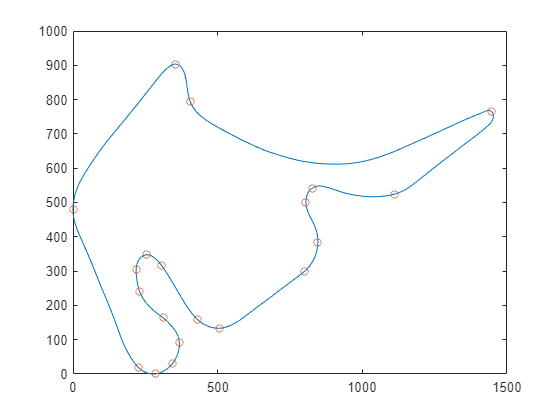

plot(x_norm, y_norm)
hold on

% Creates an array of every apex on the track
k = 1;
for i = 1:length(TrackData)
    if ismember(i,apexes)
        apex(k,1) = TrackData(i,1);
        apex(k,2) = TrackData(i,2);
        isApex(i) = 1;
        k = k + 1;
    else
        isApex(i) = 0;
    end
end
scatter(apex(1:end,1),apex(1:end,2),30) % Draws points for every apex on the track






%  % Calculate Corner radiuses
% %X = [x_norm; y_norm]; 
% X = [x_norm', y_norm']; 
% [L2,R2,K2] = curvature(X);
% 
% % Add missing first and last corner radius
% R2(1) = R2(2);
% R2(end) = R2(end-1);
% 
% direction = zeros(1,length(x_lap));
%             
% % Determine direction of the radius R
% for k =2:length(x_lap)-1
%     
%     m(k) = (y_lap(k)-y_lap(k-1))/(x_lap(k)-x_lap(k-1));
%     
%     if x_lap(k) < x_lap(k-1)
%         Yfiktiv = m(k)*abs((x_lap(k+1)-x_lap(k)))+y_lap(k+1);
%     else
%        Yfiktiv = -m(k)*abs((x_lap(k+1)-x_lap(k)))+y_lap(k+1);
%     end
%     
%     if x_lap(k) < x_lap(k-1) && Yfiktiv < y_lap(k)
%         direction(k) = -1;
%         
%     elseif x_lap(k) < x_lap(k-1) && Yfiktiv > y_lap(k)
%         direction(k) = 1;
%         
%     elseif x_lap(k) > x_lap(k-1) && Yfiktiv < y_lap(k)
%         direction(k) = 1;   
%         
%     elseif x_lap(k) > x_lap(k-1) && Yfiktiv > y_lap(k)
%         direction(k) = -1;
%     end                    
% end         
% 
% direction(1) = direction(2);
% direction(end) = direction(end-1);
% 
% for i = 1:length(R2)
%     if(R2(i)) > 200 
%         R2(i) = 200;
%     end
% end

%plot(R2)



function [L,R,k] = curvature(X)
    % Radius of curvature and curvature vector for 2D or 3D curve
    %  [L,R,k] = curvature(X)
    %   X:   2 or 3 column array of x, y (and possibly z) coordiates
    %   L:   Cumulative arc length
    %   R:   Radius of curvature
    %   k:   Curvature vector
    % The scalar curvature value is 1./R
    % Version 2.6: Calculates end point values for closed curve
      N = size(X,1);
      dims = size(X,2);
      if dims == 2
        X = [X,zeros(N,1)];  % Use 3D expressions for 2D as well
      end
      L = zeros(N,1);
      R = NaN(N,1);
      k = NaN(N,3);
      for i = 2:N-1
        [R(i),~,k(i,:)] = circumcenter(X(i,:)',X(i-1,:)',X(i+1,:)');
        L(i) = L(i-1)+norm(X(i,:)-X(i-1,:));
      end
      if norm(X(1,:)-X(end,:)) < 1e-10 % Closed curve. 
        [R(1),~,k(1,:)] = circumcenter(X(end-1,:)',X(1,:)',X(2,:)');
        R(end) = R(1);
        k(end,:) = k(1,:);
        L(end) = L(end-1) + norm(X(end,:)-X(end-1,:));
      end
      i = N;
      L(i) = L(i-1)+norm(X(i,:)-X(i-1,:));
      if dims == 2
        k = k(:,1:2);
      end
end

function [R,M,k] = circumcenter(A,B,C)
    % Center and radius of the circumscribed circle for the triangle ABC
    %  A,B,C  3D coordinate vectors for the triangle corners
    %  R      Radius
    %  M      3D coordinate vector for the center
    %  k      Vector of length 1/R in the direction from A towards M
    %         (Curvature vector)
      D = cross(B-A,C-A);
      b = norm(A-C);
      c = norm(A-B);
      if nargout == 1
        a = norm(B-C);     % slightly faster if only R is required
        R = a*b*c/2/norm(D);
        return
      end
      E = cross(D,B-A);
      F = cross(D,C-A);  
      G = (b^2*E-c^2*F)/norm(D)^2/2;
      M = A + G;
      R = norm(G);  % Radius of curvature
      if R == 0
        k = G;
      else
        k = G'/R^2;   % Curvature vector
      end
end